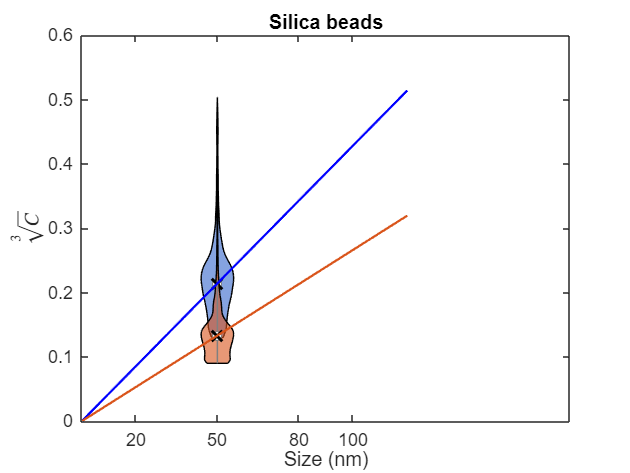

% % W5
% load('spfi_w5_440.mat');
% name440 = who('-file', 'spfi_w5_440.mat');
% S440 = eval(name440{1});
% 
% load('spfi_w5_740.mat');
% name740 = who('-file', 'spfi_w5_740.mat');
% S740 = eval(name740{1});
% 
% % Données
% iSCAT440 = S440.iSCAT440;
% RVT440 = S440.RVT;
% iSCAT740 = S740.iSCAT740;
% RVT740 = S740.RVT;
% 
% % Filtrage
% mask440 = (iSCAT440 > (0.17)^3) & (RVT440 < 3);% & (iSCAT440 < (0.25)^3);
% filtered440 = iSCAT440(mask440).^(1/3);
% 
% mask740 = (iSCAT740 > (0.17)^3) & (RVT740 < 3);% & (iSCAT740 < (0.25)^3);
% filtered740 = iSCAT740(mask740).^(1/3);



% Préparation figure
figure; hold on;

% Paramètres pour étirer/décaler les violons
stretch_factor = 20;

% % Affichage du premier violon (bleu)
% x1 = 100;
% v1 = violinplot(filtered440, ones(size(filtered440)));
% vX1 = get(v1(1).ViolinPlot, 'XData');
% newX1 = (vX1 - 1) * stretch_factor + x1;
% set(v1(1).ViolinPlot, 'XData', newX1, ...
%     'FaceColor', [0.2 0.4 0.8], ...
%     'EdgeColor', 'k', ...
%     'FaceAlpha', 0.6);
% % Après avoir tracé v1 (le bleu)
% set(v1(1).ScatterPlot, 'Visible', 'off');
% 
% % Déplacement des éléments internes
% dx1 = x1 - 1;
% move = @(h, dx) set(h, 'XData', get(h, 'XData') + dx);
% if isgraphics(v1(1).ScatterPlot), move(v1(1).ScatterPlot, dx1); end
% if isgraphics(v1(1).BoxPlot),     move(v1(1).BoxPlot, dx1);     end
% if isgraphics(v1(1).WhiskerPlot), move(v1(1).WhiskerPlot, dx1); end
% if isgraphics(v1(1).MedianPlot),  move(v1(1).MedianPlot, dx1);  end
% plot(x1, median(filtered440), 'kx', 'MarkerSize', 10, 'LineWidth', 2);
% 
% % Deuxième violon (orange)
% x2 = 100;
% v2 = violinplot(filtered740, ones(size(filtered740)));
% vX2 = get(v2(1).ViolinPlot, 'XData');
% newX2 = (vX2 - 1) * stretch_factor + x2;
% set(v2(1).ViolinPlot, 'XData', newX2, ...
%     'FaceColor', [0.85 0.33 0.1], ...
%     'EdgeColor', 'k', ...
%     'FaceAlpha', 0.6);
% % Après avoir tracé v2 (l’orange)
% set(v2(1).ScatterPlot, 'Visible', 'off');
% 
% dx2 = x2 - 1;
% if isgraphics(v2(1).ScatterPlot), move(v2(1).ScatterPlot, dx2); end
% if isgraphics(v2(1).BoxPlot),     move(v2(1).BoxPlot, dx2);     end
% if isgraphics(v2(1).WhiskerPlot), move(v2(1).WhiskerPlot, dx2); end
% if isgraphics(v2(1).MedianPlot),  move(v2(1).MedianPlot, dx2);  end
% plot(x2, median(filtered740), 'kx', 'MarkerSize', 10, 'LineWidth', 2);


%W2
load('spfi_w3_440.mat');
name440 = who('-file', 'spfi_w3_440.mat');
S440 = eval(name440{1});

load('spfi_w3_740.mat');
name740 = who('-file', 'spfi_w3_740.mat');
S740 = eval(name740{1});


% Données
iSCAT440 = S440.iSCAT440;
RVT440 = S440.RVT;
iSCAT740 = S740.iSCAT740;
RVT740 = S740.RVT;

% Filtrage
mask440_w2 = (iSCAT440 > (0.13)^3) & (RVT440 < 2); %& (iSCAT440 < (0.25)^3);
filtered440_w2 = iSCAT440(mask440_w2).^(1/3);
mask740_w2 = (iSCAT740 > (0.09)^3) & (RVT740 < 3); %& (iSCAT740 < (0.25)^3);
filtered740_w2 = iSCAT740(mask740_w2).^(1/3);

% troisième violon (bleu)
x3 = 50;
v3 = violinplot(filtered440_w2, ones(size(filtered440_w2)));
vX3 = get(v3(1).ViolinPlot, 'XData');
newX3 = (vX3 - 1) * stretch_factor + x3;
set(v3(1).ViolinPlot, 'XData', newX3, ...
    'FaceColor', [0.2 0.4 0.8], ...
    'EdgeColor', 'k', ...
    'FaceAlpha', 0.6);
% Après avoir tracé v3 (l’orange)
set(v3(1).ScatterPlot, 'Visible', 'off');

dx3 = x3 - 1;
if isgraphics(v3(1).ScatterPlot), move(v3(1).ScatterPlot, dx3); end
if isgraphics(v3(1).BoxPlot),     move(v3(1).BoxPlot, dx3);     end
if isgraphics(v3(1).WhiskerPlot), move(v3(1).WhiskerPlot, dx3); end
if isgraphics(v3(1).MedianPlot),  move(v3(1).MedianPlot, dx3);  end
plot(x3, median(filtered440_w2), 'kx', 'MarkerSize', 10, 'LineWidth', 2);

% quatrième violon (orange)
x4 = 50;
v4 = violinplot(filtered740_w2, ones(size(filtered740_w2)));
vX4 = get(v4(1).ViolinPlot, 'XData');
newX4 = (vX4 - 1) * stretch_factor + x4;
set(v4(1).ViolinPlot, 'XData', newX4, ...
    'FaceColor', [0.85 0.33 0.1], ...
    'EdgeColor', 'k', ...
    'FaceAlpha', 0.6);
% Après avoir tracé v2 (l’orange)
set(v4(1).ScatterPlot, 'Visible', 'off');

dx4 = x4 - 1;
if isgraphics(v4(1).ScatterPlot), move(v4(1).ScatterPlot, dx4); end
if isgraphics(v4(1).BoxPlot),     move(v4(1).BoxPlot, dx4);     end
if isgraphics(v4(1).WhiskerPlot), move(v4(1).WhiskerPlot, dx4); end
if isgraphics(v4(1).MedianPlot),  move(v4(1).MedianPlot, dx4);  end
plot(x4, median(filtered740_w2), 'kx', 'MarkerSize', 10, 'LineWidth', 2);

% %W3
% load('spfi_440_w3.mat');
% name440 = who('-file', 'spfi_440_w3.mat');
% S440 = eval(name440{1});
% 
% load('spfi_740_w3.mat');
% name740 = who('-file', 'spfi_740_w3.mat');
% S740 = eval(name740{1});
% 
% 
% % Données
% iSCAT440 = S440.iSCAT440;
% RVT440 = S440.RVT;
% iSCAT740 = S740.iSCAT740;
% RVT740 = S740.RVT;
% 
% % Filtrage
% mask440_w3= (iSCAT440 > (0.18)^3) & (RVT440 < 2) & (iSCAT440 < (0.25)^3);
% filtered440_w3 = iSCAT440(mask440_w3).^(1/3);
% mask740_w3 = (iSCAT740 > (0.13)^3) & (RVT740 < 3) & (iSCAT740 < (0.25)^3);
% filtered740_w3 = iSCAT740(mask740_w3).^(1/3);
% 
% % Cinquième violon (bleu)
% x5 = 50;
% v5 = violinplot(filtered440_w3, ones(size(filtered440_w3)));
% vX5 = get(v5(1).ViolinPlot, 'XData');
% newX5 = (vX5 - 1) * stretch_factor + x5;
% set(v5(1).ViolinPlot, 'XData', newX5, ...
%     'FaceColor', [0.2 0.4 0.8], ...
%     'EdgeColor', 'k', ...
%     'FaceAlpha', 0.6);
% % Après avoir tracé v5 (l’orange)
% set(v5(1).ScatterPlot, 'Visible', 'off');
% 
% dx5 = x5 - 1;
% if isgraphics(v5(1).ScatterPlot), move(v5(1).ScatterPlot, dx5); end
% if isgraphics(v5(1).BoxPlot),     move(v5(1).BoxPlot, dx5);     end
% if isgraphics(v5(1).WhiskerPlot), move(v5(1).WhiskerPlot, dx5); end
% if isgraphics(v5(1).MedianPlot),  move(v5(1).MedianPlot, dx5);  end
% plot(x5, median(filtered440_w3), 'kx', 'MarkerSize', 10, 'LineWidth', 2);
% 
% % Sixième violon (orange)
% x6 = 50;
% v6 = violinplot(filtered740_w3, ones(size(filtered740_w3)));
% vX6 = get(v6(1).ViolinPlot, 'XData');
% newX6 = (vX6 - 1) * stretch_factor + x6;
% set(v6(1).ViolinPlot, 'XData', newX6, ...
%     'FaceColor', [0.85 0.33 0.1], ...
%     'EdgeColor', 'k', ...
%     'FaceAlpha', 0.6);
% % Après avoir tracé v2 (l’orange)
% set(v6(1).ScatterPlot, 'Visible', 'off');
% 
% dx6 = x6 - 1;
% if isgraphics(v6(1).ScatterPlot), move(v6(1).ScatterPlot, dx6); end
% if isgraphics(v6(1).BoxPlot),     move(v6(1).BoxPlot, dx6);     end
% if isgraphics(v6(1).WhiskerPlot), move(v6(1).WhiskerPlot, dx6); end
% if isgraphics(v6(1).MedianPlot),  move(v6(1).MedianPlot, dx6);  end
% plot(x6, median(filtered740_w3), 'kx', 'MarkerSize', 10, 'LineWidth', 2);
% 
% %W4
% load('spfi_440_w4.mat');
% name440 = who('-file', 'spfi_440_w4.mat');
% S440 = eval(name440{1});
% 
% load('spfi_740_w4.mat');
% name740 = who('-file', 'spfi_740_w4.mat');
% S740 = eval(name740{1});
% 
% 
% % Données
% iSCAT440 = S440.iSCAT440;
% RVT440 = S440.RVT;
% iSCAT740 = S740.iSCAT740;
% RVT740 = S740.RVT;
% 
% % Filtrage
% mask440_w4= (iSCAT440 > (0.15)^3) & (RVT440 < 2) & (iSCAT440 < (0.27)^3);
% filtered440_w4 = iSCAT440(mask440_w4).^(1/3);
% mask740_w4 = (iSCAT740 > (0.13)^3) & (RVT740 < 3) & (iSCAT740 < (0.3)^3);
% filtered740_w4 = iSCAT740(mask740_w4).^(1/3);
% 
% % septieme violon (bleu)
% x7 = 80;
% v7 = violinplot(filtered440_w4, ones(size(filtered440_w4)));
% vX7 = get(v7(1).ViolinPlot, 'XData');
% newX7 = (vX7 - 1) * stretch_factor + x7;
% set(v7(1).ViolinPlot, 'XData', newX7, ...
%     'FaceColor', [0.2 0.4 0.8], ...
%     'EdgeColor', 'k', ...
%     'FaceAlpha', 0.6);
% % Après avoir tracé v7 (l’orange)
% set(v7(1).ScatterPlot, 'Visible', 'off');
% 
% dx7 = x7 - 1;
% if isgraphics(v7(1).ScatterPlot), move(v7(1).ScatterPlot, dx7); end
% if isgraphics(v7(1).BoxPlot),     move(v7(1).BoxPlot, dx7);     end
% if isgraphics(v7(1).WhiskerPlot), move(v7(1).WhiskerPlot, dx7); end
% if isgraphics(v7(1).MedianPlot),  move(v7(1).MedianPlot, dx7);  end
% plot(x7, median(filtered440_w4), 'kx', 'MarkerSize', 10, 'LineWidth', 2);
% 
% % huitième violon (orange)
% x8 = 80;
% v8 = violinplot(filtered740_w4, ones(size(filtered740_w4)));
% vX8 = get(v8(1).ViolinPlot, 'XData');
% newX8 = (vX8 - 1) * stretch_factor + x8;
% set(v8(1).ViolinPlot, 'XData', newX8, ...
%     'FaceColor', [0.85 0.33 0.1], ...
%     'EdgeColor', 'k', ...
%     'FaceAlpha', 0.6);
% % Après avoir tracé v8 (l’orange)
% set(v8(1).ScatterPlot, 'Visible', 'off');
% 
% dx8 = x8 - 1;
% if isgraphics(v8(1).ScatterPlot), move(v8(1).ScatterPlot, dx8); end
% if isgraphics(v8(1).BoxPlot),     move(v8(1).BoxPlot, dx8);     end
% if isgraphics(v8(1).WhiskerPlot), move(v8(1).WhiskerPlot, dx8); end
% if isgraphics(v8(1).MedianPlot),  move(v8(1).MedianPlot, dx8);  end
% plot(x8, median(filtered740_w4), 'kx', 'MarkerSize', 10, 'LineWidth', 2);
% 
% %W6
% load('spfi_440_w6.mat');
% name440 = who('-file', 'spfi_440_w6.mat');
% S440 = eval(name440{1});
% 
% load('spfi_740_w6.mat');
% name740 = who('-file', 'spfi_740_w6.mat');
% S740 = eval(name740{1});
% 
% 
% % Données
% iSCAT440 = S440.iSCAT440;
% RVT440 = S440.RVT;
% iSCAT740 = S740.iSCAT740;
% RVT740 = S740.RVT;
% 
% % Filtrage
% mask440_w6= (iSCAT440 > (0.2)^3) & (RVT440 < 2); %& (iSCAT440 < (0.25)^3);
% filtered440_w6 = iSCAT440(mask440_w6).^(1/3);
% mask740_w6 = (iSCAT740 > (0.2)^3) & (RVT740 < 3); %& (iSCAT740 < (0.25)^3);
% filtered740_w6 = iSCAT740(mask740_w6).^(1/3);
% 
% % neuvième violon (bleu)
% x9 = 200;
% v9 = violinplot(filtered440_w6, ones(size(filtered440_w6)));
% vX9 = get(v9(1).ViolinPlot, 'XData');
% newX9 = (vX9 - 1) * stretch_factor + x9;
% set(v9(1).ViolinPlot, 'XData', newX9, ...
%     'FaceColor', [0.2 0.4 0.8], ...
%     'EdgeColor', 'k', ...
%     'FaceAlpha', 0.6);
% % Après avoir tracé v9 (l’orange)
% set(v9(1).ScatterPlot, 'Visible', 'off');
% 
% dx9 = x9 - 1;
% if isgraphics(v9(1).ScatterPlot), move(v9(1).ScatterPlot, dx9); end
% if isgraphics(v9(1).BoxPlot),     move(v9(1).BoxPlot, dx9);     end
% if isgraphics(v9(1).WhiskerPlot), move(v9(1).WhiskerPlot, dx9); end
% if isgraphics(v9(1).MedianPlot),  move(v9(1).MedianPlot, dx9);  end
% plot(x9, median(filtered440_w6), 'kx', 'MarkerSize', 10, 'LineWidth', 2);
% 
% % dixième violon (orange)
% x10 = 200;
% v10 = violinplot(filtered740_w6, ones(size(filtered740_w6)));
% vX10 = get(v10(1).ViolinPlot, 'XData');
% newX10 = (vX10 - 1) * stretch_factor + x10;
% set(v10(1).ViolinPlot, 'XData', newX10, ...
%     'FaceColor', [0.85 0.33 0.1], ...
%     'EdgeColor', 'k', ...
%     'FaceAlpha', 0.6);
% % Après avoir tracé v10 (l’orange)
% set(v10(1).ScatterPlot, 'Visible', 'off');
% 
% dx10 = x10 - 1;
% if isgraphics(v10(1).ScatterPlot), move(v10(1).ScatterPlot, dx10); end
% if isgraphics(v10(1).BoxPlot),     move(v10(1).BoxPlot, dx10);     end
% if isgraphics(v10(1).WhiskerPlot), move(v10(1).WhiskerPlot, dx10); end
% if isgraphics(v10(1).MedianPlot),  move(v10(1).MedianPlot, dx10);  end
% plot(x10, median(filtered740_w6), 'kx', 'MarkerSize', 10, 'LineWidth', 2);


% Axes
xlim([0 180]);
ylim([0 0.6]);
xlabel('Size (nm)');
ylabel('$$\sqrt[3]{\it{C}}$$', 'Interpreter', 'latex');
title('Silica beads');
xticks([20 50 80 100]);
xticklabels({'20', '50', '80', '100'});
set(gca, 'FontSize', 12);
box on;
% Données x (positions en nm)
x_bleu = [50]; % positions des violons bleus
y_bleu = [median(filtered440_w2)];

x_orange = [50]; % positions des violons oranges
y_orange = [median(filtered740_w2)];

% Régressions linéaires passant par l'origine : y = a*x
% => a = (x'*y) / (x'*x)
a_bleu = (x_bleu * y_bleu') / (x_bleu * x_bleu');
a_orange = (x_orange * y_orange') / (x_orange * x_orange');

% Affichage dans la console
% fprintf('Pente courbe bleue (coefficient directeur): %.4f\n', a_bleu);
% fprintf('Pente courbe orange (coefficient directeur): %.4f\n', a_orange);


% Tracé des droites
x_fit = linspace(0, 120, 100);
y_fit_bleu = a_bleu * x_fit;
y_fit_orange = a_orange * x_fit;

plot(x_fit, y_fit_bleu, 'b-', 'LineWidth', 1.5);
plot(x_fit, y_fit_orange, 'Color', [0.85 0.33 0.1], 'LineWidth', 1.5);

%calcul LOD
Cmin_bleu = 0.1;
Cmin_orange = 0.1;
LOD_bleu = (1/a_bleu)*Cmin_bleu;
LOD_orange = (1/a_orange)*Cmin_orange;
LOD = (LOD_orange + LOD_bleu)/2

LOD = 30.4432

fprintf('LOD 440 nm is: %.2f\n', LOD_bleu);

LOD 440 nm is: 23.34


fprintf('LOD 740 nm is : %.2f\n', LOD_orange);

LOD 740 nm is : 37.55


fprintf('avarage LOD is: %.2f\n', LOD);

avarage LOD is: 30.44
